# Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizi una cifra di merito.

Si possono scegliere tanti vincoli e cifre di merito, ma la struttura base rimane simile.

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=K_p \left(1+\frac{1}{T_i s} \right)=\frac{K_p\cdot s+K_i}{s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load modello_jnt2.mat
sys_vel_motore=tf(modello_giunto);

Inserisco il filtro notch (volendo si può pensare di ottimizzare anche i coefficienti del filtro) 

IMPORTANTE: *il filtro notch se lo aggiungete qui, va anche implementato!*

wn=290;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
Plant=sys_vel_motore*notch;

% Function handle for the process and controller frequency responses
process_frequency_response = @(w)reshape( freqresp(Plant,w), length(w),1);
controller_frequency_response = @pi_frequency_response;


I vincoli sono (potete modificarli, aggiungerne, toglierne)

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

% Loop shaping condition parameters
desired_wc = 80;
desired_phase_margin = 70;
desired_maximum_sensitivity = 2;
low_freq_disturbance_attenuation = 0.1;
low_freq_threshold = 0.001;
high_freq_noise_attenuation = 0.1;
high_freq_threshold = 500;

% Frequency vector for evaluation (logarithmic scale)
frequency_vector = logspace(-5, 5, 100000)';
frequency_vector = sort([frequency_vector; low_freq_threshold; high_freq_threshold]);

% Define optimization constraints using the constraints function
optim_constraints = @(controller_parameters) constraints(controller_parameters, ...
    controller_frequency_response, ...
    process_frequency_response, ...
    desired_maximum_sensitivity, ...
    desired_phase_margin, ...
    low_freq_disturbance_attenuation, ...
    low_freq_threshold, ...
    high_freq_noise_attenuation, ...
    high_freq_threshold, ...
    frequency_vector);

Scelgo la cifra di merito 


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


(alternativa $J=-\omega_c$ massimizzare la pulsazione di taglio)

con $\omega_c$ la frequenza (pulsazione) di taglio, e $\omega_{c,des}$ il valore desiderato.

Le incognite del problema sono $x=[K_p,\;K_i]$

% Define the desired cutting frequency for the control loop:
wc_des = 200;

% Define optimization fitness function using the fitness_wc function
optim_fitness = @(controller_parameters) fitness(controller_parameters, ...
    controller_frequency_response, ...
    process_frequency_response, ...
    desired_wc, ...
    frequency_vector);

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

Come valori iniziali, scelgo $T_i$ in modo che la sua pulsazione sia due decadi prima di $\omega_c$ quindi $\frac{1}{T_i}=0.01\omega_c$ e $K_p$ per imporre di tagliare a $\omega_c$. Altre condizioni iniziali possono essere ugualmente valide

% Set the integral time constant 'Ti' based on the desired cutting frequency:
Ti = 1 / (0.01 * wc_des);

% Define the Laplace variable 's' for use in transfer function expressions:
s = tf('s');

% Design the Proportional-Integral (PI) controller transfer function 'C=Kp*C0':
C0 = 1 + 1 / (Ti * s);

% Compute the controller by setting the proportional gain 'Kp' such that
% |C * Plant| = 1 at the desired cutting frequency 'wc_des':
Kp = 1 / abs(freqresp(C0 * Plant, wc_des));


% Initial guess for the optimization variable 'x0':
x0 = [Kp, Ti];

% Define lower and upper bounds for the optimization variable:
lower_bound = [0.0001, 0.01];
upper_bound = [10000, 10000];


LOCAL_OPTIMIZATION=false;

if LOCAL_OPTIMIZATION
    % Use fmincon to optimize the controller parameters to minimize the cost
    % function subject to the defined constraints:
    [x, fval, exitflag] = fmincon(optim_fitness, x0, [], [], [], [], lower_bound, upper_bound, optim_constraints);


else
    % Create a GlobalSearch object 'gs' with iterative display:
    gs = GlobalSearch('Display', 'iter');

    % Define the optimization problem using createOptimProblem:
    problem = createOptimProblem('fmincon', 'x0', x0, ...
        'objective', optim_fitness, 'lb', lower_bound, 'ub', upper_bound, 'nonlcon', optim_constraints);

    % Run the global optimization algorithm on the defined problem:
    [x, fval, exitflag] = run(gs, problem);

    % The GlobalSearch algorithm is used to perform a global optimization of
    % the cost function subject to the nonlinear constraints defined by 'nlcon'.
    % The optimization is started from the initial guess 'x0' within the bounds
    % specified by 'lower_bound' and 'upper_bound'. The results are stored in
    % 'x' (optimized variable values), 'fval' (optimized function value), and
    % 'exitflag' (exit flag indicating the optimization status).

end


 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       42        5037                                    5037            1    Initial Point
     200     1269        5037                                    5037            1    Stage 1 Local
     245     1356        5037          6400         7254         5037            1    Stage 2 Local
     266     1413        5037          6400         6400         5037            1    Stage 2 Local
     298     1472        5037          6798         7680         5037            1    Stage 2 Local
     300     1474        5037     8.217e+04         6798                              Stage 2 Search
     320     1505        5037          6400         8158         6400            2    Stage 2 Local
     348     1560        5037          5439         7680         5037            1    Stage 2 Loca


% Check the exit flag to ensure successful optimization:
if exitflag <= 0
    error("Optimization failed: Check constraints or initial guess");
else
    fprintf('Optimization successful\n');
end

Optimization successful


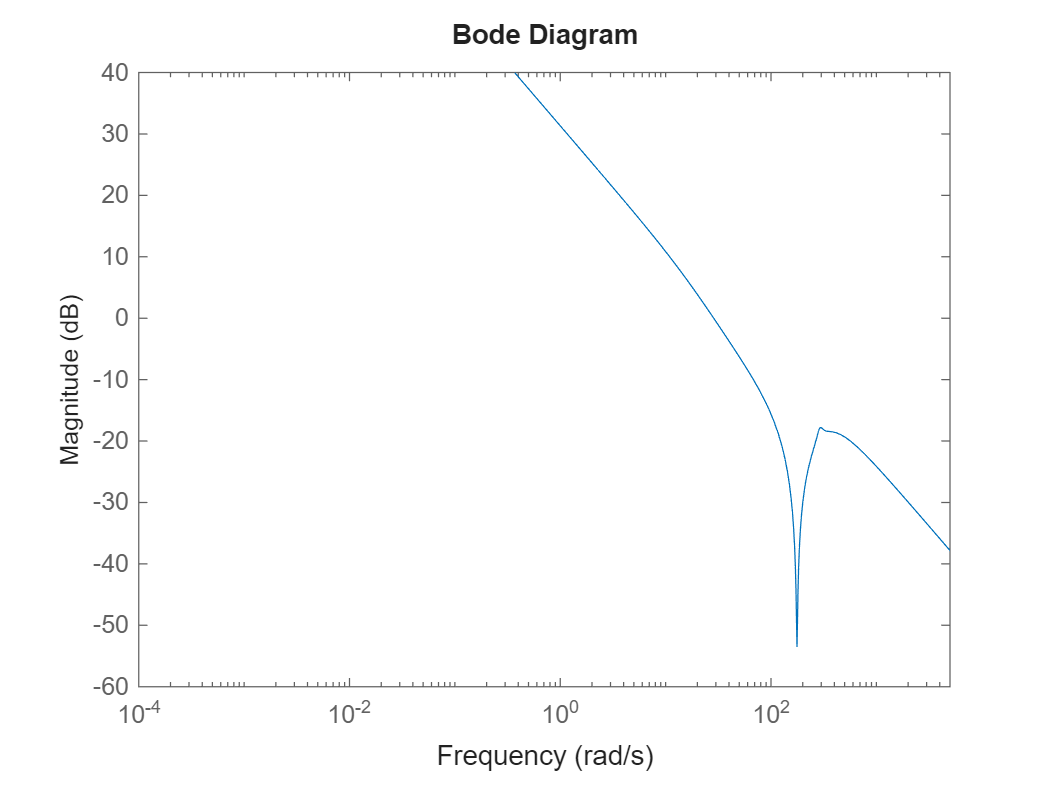

% Extract the optimized controller gains from the optimization variable 'x':
Ti = x(1);
Kp = x(2);

Ki=Kp/Ti;
% Construct the PI controller transfer function 'C':
C = tf([Kp, Ki], [1, 0]);

% Plot the Bode magnitude plot of the closed-loop system (C * Plant):
figure;
bodemag(C * Plant);
hold on;

% Calculate and plot the disturbance reduction constraint at low frequencies:
Lmin_low_freq = 1 / low_freq_disturbance_attenuation * abs(freqresp(Plant, low_freq_threshold));
plot(low_freq_threshold, 20 * log10(Lmin_low_freq), 'k*');

% Add lines to emphasize the disturbance reduction constraint:
semilogx([0.1 * low_freq_threshold, low_freq_threshold, low_freq_threshold], ...
    20 * log10([Lmin_low_freq, Lmin_low_freq, Lmin_low_freq * 0.1]), 'k');

% Calculate and plot the noise reduction constraint at high frequencies:
Lmax_high_freq = high_freq_noise_attenuation;
plot(high_freq_threshold, 20 * log10(Lmax_high_freq), 'r*');

% Add lines to emphasize the noise reduction constraint:
semilogx([high_freq_threshold, high_freq_threshold, high_freq_threshold * 10], ...
    20 * log10([Lmax_high_freq * 10, Lmax_high_freq, Lmax_high_freq]), 'r');

% Set the x-axis limits to focus on the relevant frequency range:
xlim([0.1 * low_freq_threshold, 10 * high_freq_threshold]);

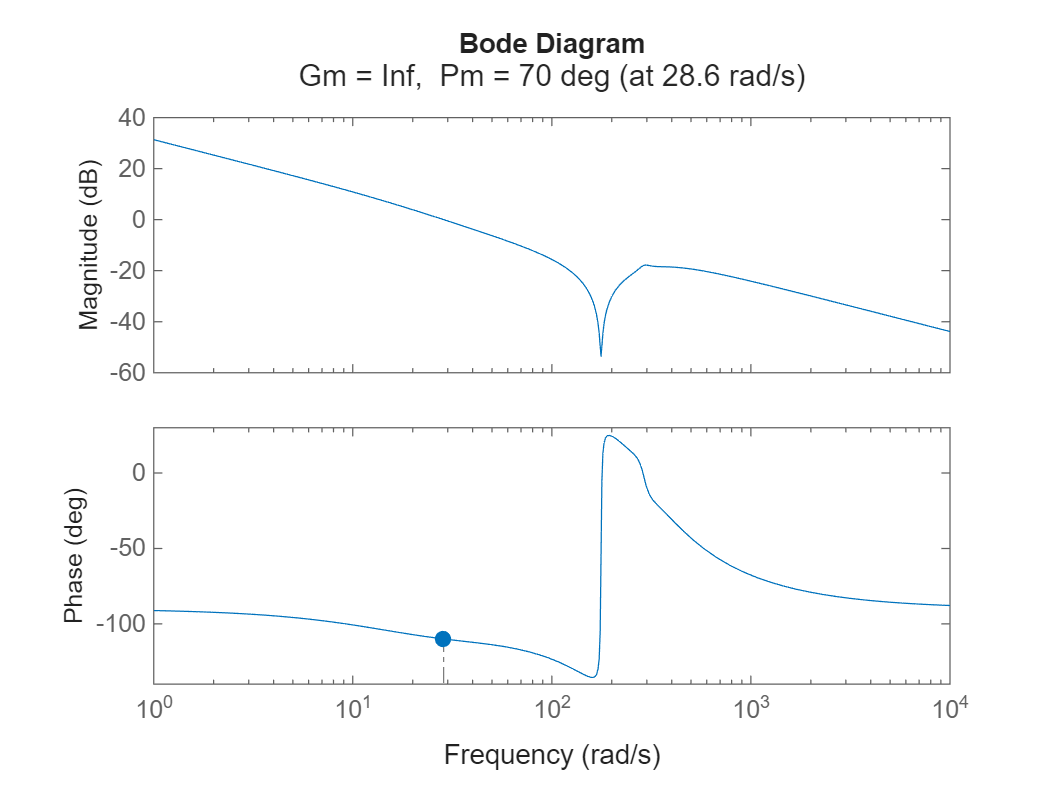


% Create a new figure for the stability margin plot:
figure;
margin(C * Plant);

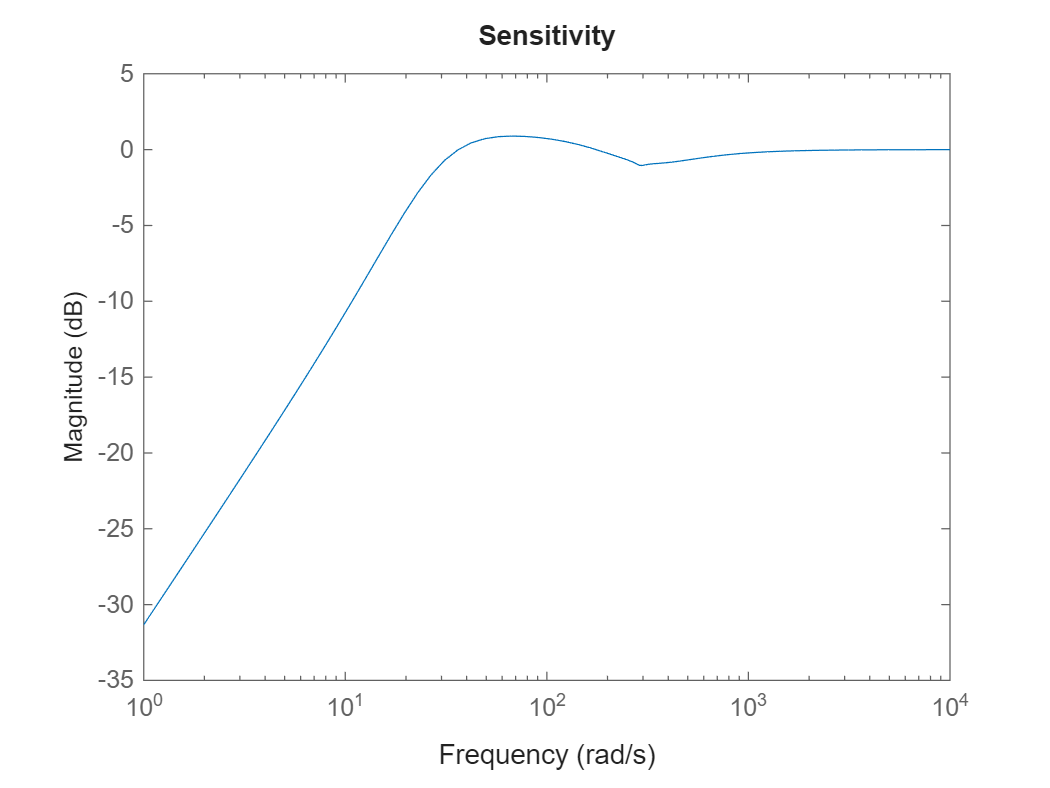


% Create a new figure for the Bode magnitude plot of the sensitivity function:
figure;
bodemag(1 / (1 + C * Plant));
hold on;

% Add a horizontal dashed line at the level of 20*log10(MS) to represent the
% maximum sensitivity constraint:
semilogx(xlim, 20 * log10(desired_maximum_sensitivity) * [1, 1], '--k');

% Set the title of the plot:
title('Sensitivity');


% The Bode magnitude plot illustrates the sensitivity function |S| = 1 / |1 + L|,
% where L is the open-loop transfer function (C * Plant). The horizontal dashed
% line indicates the specified maximum sensitivity (MS) level.




